# **Vision Artificial. GIEC-GITT.**

# **Sistemas de Vision Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre:**

**Fecha:**

# Tema 4. Ejercicio 4. *Local features*

## Localización de esquinas utilizando el algoritmo FAST

El objetivo de esta práctica es comprobar la capacidad de las características FAST para localizar esquinas en imágenes diferentes. Para ello:

- Utilice `corners = detectFASTFeatures(I)` sobre la imagen 'ladrillos1.jpg', y visualice las esquinas sobre ella con la instrucción `plot(corners.selectStrongest(25))`;

- Aumente el número de esquinas a detectar, para comprobar que las que se incorporan son más débiles que las iniciales.

- Pruebe sobre diferentes imágenes (texture-pattern2.png, rice.tif, etc.) para identificar aquellas en las que estas características pueden resultar más útiles.

## Uso de características LBP para distinguir imágenes con texturas diferentes

El objetivo de este ejercicio es verificar el comportamiento de las caracteristicas LBP en imágenes con texturas diferentes. Para ello:

- Abra y muestre las imágenes texture-canvas.png, gotas.jpg, ladrillos2.jpg, ladrillos3.jpg y ladrillos4.jpg y calcule sus características LBP con la instrucción `LBPImag1 = extractLBPFeatures(Imag1,'Upright',false). `

- Visualice las características con `bar(LBPImag1)`. ¿Se parecen entre sí las características de las distintas imágenes? Utilice la función subplot para visualizar todas las imágenes y características y así poder realizar la comparación fácilmente.

- Calcule la distancia entre las características LBP de ladrillos3.jpg y cada una de las demás imágenes, utilizando la instrucción `DistImag1_2 = norm (LBPImag1 - LBPImag2)`. Analice los resultados. ¿Son coherentes con lo que se puede verificar visualmente?

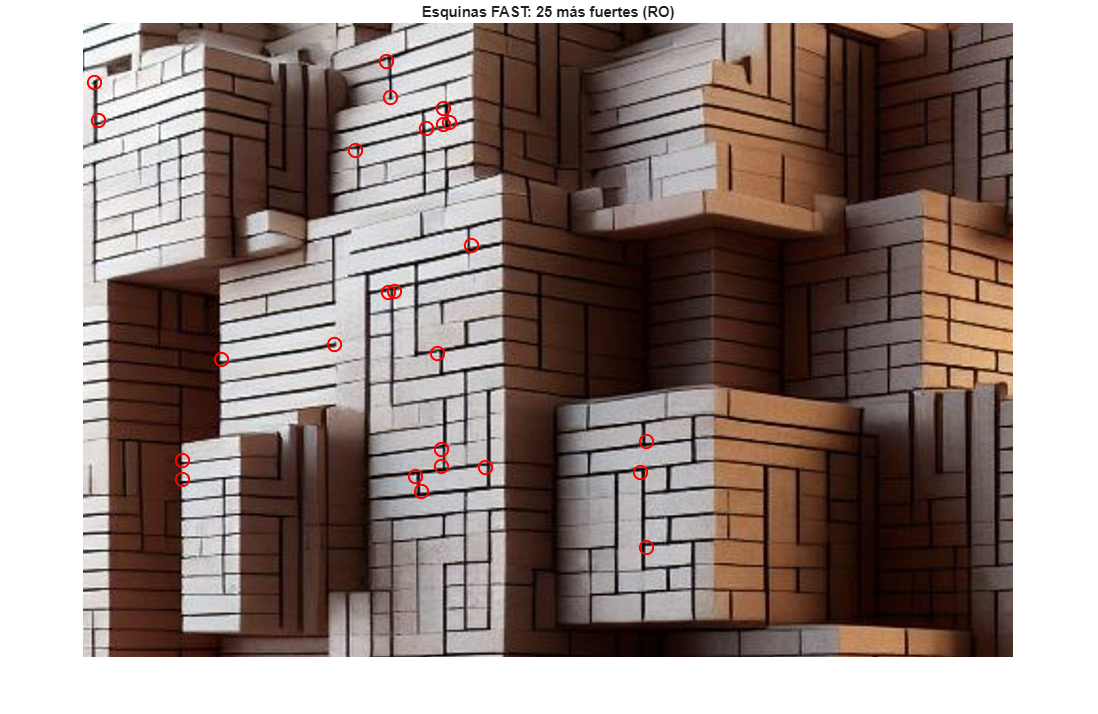

% === EJERCICIO 4: FAST Y LBP ===
clear all; close all;

% --- FUNCIÓN AUXILIAR PARA GARANTIZAR ESCALA DE GRISES (2-D) ---
function I_gray = ensureGrayscale(I)
    % Convierte la imagen I a escala de grises (2D).
    if isempty(I)
        I_gray = [];
        return;
    end
    
    if size(I, 3) == 3
        % Es RGB, convertir a escala de grises
        I_gray = rgb2gray(I);
    elseif islogical(I) || isa(I, 'uint8') || isa(I, 'uint16') || isa(I, 'double')
        % Ya es una imagen de intensidad (o binaria), usar directamente o convertir a double si es necesario
        % La mayoría de las funciones de Vision Toolbox aceptan uint8 2-D.
        I_gray = I;
    else
        % Caso de imagen indexada (X, map), aunque 'imread' sin salida de mapa 
        % debería devolver RGB si está en color o intensidad si es escala de grises.
        warning('Tipo de imagen no reconocido. Intentando usar IM2GRAY.');
        I_gray = im2gray(I); % Intentar usar im2gray como alternativa robusta
    end
end

% --- SCRIPT PRINCIPAL ---

% --- FAST: Localización de esquinas ---

I_ladrillos_RGB = imread('ladrillos1.jpg');
I_ladrillos = ensureGrayscale(I_ladrillos_RGB); % Conversión corregida

% 1. Visualizar 25 Esquinas más fuertes (Marcadores claros y grandes)
corners = detectFASTFeatures(I_ladrillos);
figure;
imshow(I_ladrillos_RGB);
title('Esquinas FAST: 25 más fuertes (RO)');
hold on;
strongestCorners = corners.selectStrongest(25);
% Aplicación de la modificación de visualización solicitada:
plot(strongestCorners.Location(:,1), strongestCorners.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);
hold off;

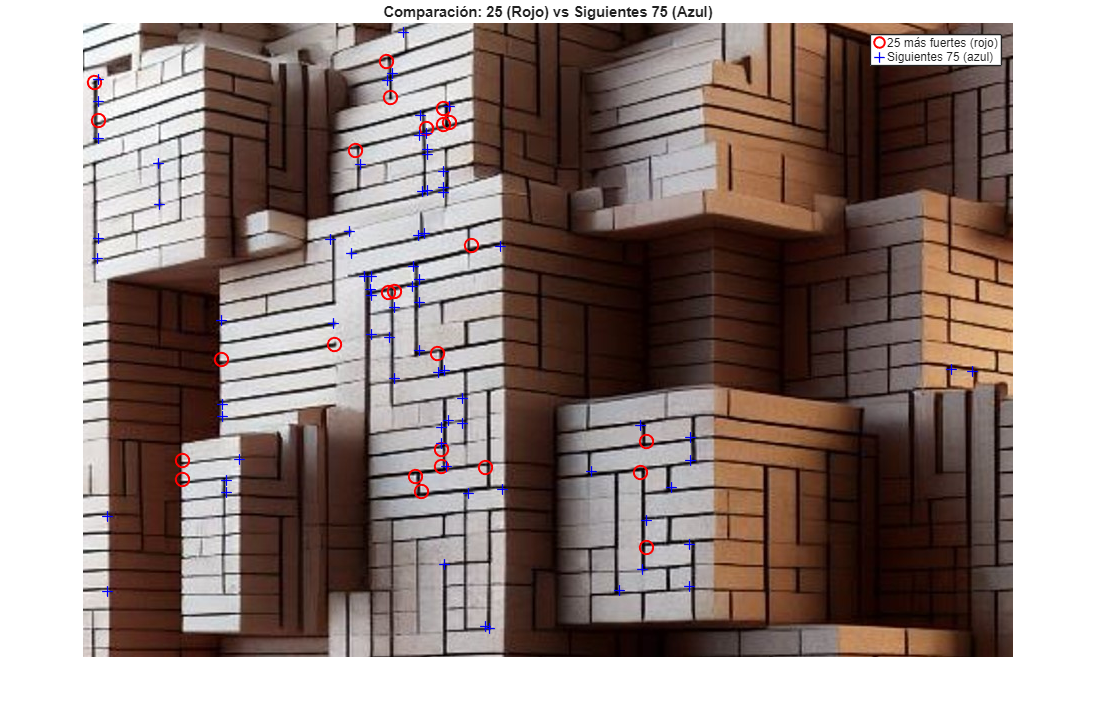


% 2. Comparación: 25 vs 100 Esquinas
figure;
imshow(I_ladrillos_RGB);
title('Comparación: 25 (Rojo) vs Siguientes 75 (Azul)');
hold on;
% 25 más fuertes (ROJO)
plot(strongestCorners.Location(:,1), strongestCorners.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);
% Siguientes 75 (AZUL)
allCorners = corners.selectStrongest(100);
weakerCorners = allCorners(26:100);
plot(weakerCorners.Location(:,1), weakerCorners.Location(:,2), 'b+', 'MarkerSize', 8, 'LineWidth', 1);
legend('25 más fuertes (rojo)', 'Siguientes 75 (azul)');
hold off;

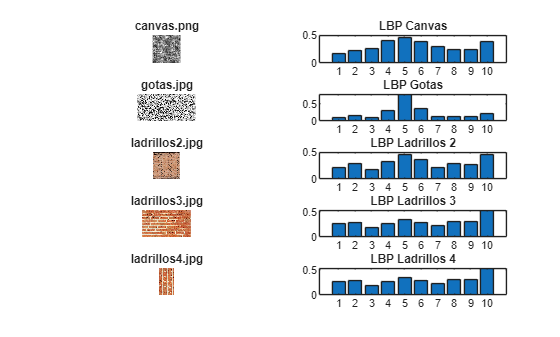



% --- LBP: Uso de características LBP para distinguir texturas ---

% Cargar imágenes
Imag1 = imread('texture-canvas.png');
Imag2 = imread('gotas.jpg');
Imag3 = imread('ladrillos2.jpg');
Imag4 = imread('ladrillos3.jpg');
Imag5 = imread('ladrillos4.jpg');

% Convertir a escala de grises (usando la función auxiliar)
Imag1_g = ensureGrayscale(Imag1);
Imag2_g = ensureGrayscale(Imag2);
Imag3_g = ensureGrayscale(Imag3);
Imag4_g = ensureGrayscale(Imag4);
Imag5_g = ensureGrayscale(Imag5);

% Calcular características LBP
LBPImag1 = extractLBPFeatures(Imag1_g, 'Upright', false);
LBPImag2 = extractLBPFeatures(Imag2_g, 'Upright', false);
LBPImag3 = extractLBPFeatures(Imag3_g, 'Upright', false);
LBPImag4 = extractLBPFeatures(Imag4_g, 'Upright', false);
LBPImag5 = extractLBPFeatures(Imag5_g, 'Upright', false);

% Visualización de imágenes y características
figure('Name', 'Imágenes y Características LBP');

subplot(5, 2, 1); imshow(Imag1); title('canvas.png');
subplot(5, 2, 2); bar(LBPImag1); title('LBP Canvas');

subplot(5, 2, 3); imshow(Imag2); title('gotas.jpg');
subplot(5, 2, 4); bar(LBPImag2); title('LBP Gotas');

subplot(5, 2, 5); imshow(Imag3); title('ladrillos2.jpg');
subplot(5, 2, 6); bar(LBPImag3); title('LBP Ladrillos 2');

subplot(5, 2, 7); imshow(Imag4); title('ladrillos3.jpg');
subplot(5, 2, 8); bar(LBPImag4); title('LBP Ladrillos 3');

subplot(5, 2, 9); imshow(Imag5); title('ladrillos4.jpg');
subplot(5, 2, 10); bar(LBPImag5); title('LBP Ladrillos 4');


% Cálculo de Distancias
DistLadrillos3_Canvas = norm(LBPImag4 - LBPImag1);
DistLadrillos3_Gotas = norm(LBPImag4 - LBPImag2);
DistLadrillos3_Ladrillos2 = norm(LBPImag4 - LBPImag3);
DistLadrillos3_Ladrillos4 = norm(LBPImag4 - LBPImag5);

fprintf('\n--- Distancias LBP desde ladrillos3.jpg ---\n');


--- Distancias LBP desde ladrillos3.jpg ---


fprintf('vs canvas.png:        %.4f\n', DistLadrillos3_Canvas);

vs canvas.png:        0.2995


fprintf('vs gotas.jpg:         %.4f\n', DistLadrillos3_Gotas);

vs gotas.jpg:         0.6500


fprintf('vs ladrillos2.jpg:    %.4f\n', DistLadrillos3_Ladrillos2);

vs ladrillos2.jpg:    0.1753


fprintf('vs ladrillos4.jpg:    %.4f\n', DistLadrillos3_Ladrillos4);

vs ladrillos4.jpg:    0.0040
